# 3.3 矩阵

## 1. 矩阵的创建方法

### 1-1 直接输入法

- 行内使用空格或者逗号隔开

- 行间使用分号或者回车隔开

a = [1 2 3 ; 4, 5, 6
    7 8 9] % 例子,四种方法都使用了

a =      1     2     3
     4     5     6
     7     8     9


### 1-2 函数创建法

#### 1-2-1 zeros / ones / eye

**① zeros 创建0矩阵**

zeros(2)    % 创建2x2的0矩阵

ans =      0     0
     0     0


zeros(2,3)  % 创建2x3的0矩阵

ans =      0     0     0
     0     0     0


**② ones 创建1矩阵**

ones(5) % 5x5

ans =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


ones(1,2)   % 1x2

ans =      1     1


**③ eye 单位矩阵:主对角线全部为1,其他位置元素为0 (得名难道来自斜眼?)**

e = eye(4)  % 单位方阵

e =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


g = eye(2,4)    % 单位矩阵

g =      1     0     0     0
     0     1     0     0


#### 1-2-1 rand / randi / randn

**①rand    创建0-1均匀分布的随机数**

rand(2,4)

ans =     0.7302    0.5841    0.9063    0.8178
    0.3439    0.1078    0.8797    0.2607


**②randi    均匀分布的随机整数(integer)**

randi([1,6] , 2 , 4)    % 向量[]括起来的是min和max范围,然后是m x n的矩阵

ans =      4     3     1     3
     1     2     2     1


**③randn    标准正态分布的随机数(Norm:正态)**

rand(2,3)   % 标准正态分布

ans =     0.5985    0.6959    0.6385
    0.4709    0.6999    0.0336


#### 1-2-3 diag / blkdiag    

**① diag   (对角 diagonal)    创建对角矩阵或者获取矩阵的对角元素**

- 情况1：如果输入的第一个参数是向量，则表示创建对角矩阵

diag([1 2 3])   % 默认放在主对角线上

ans =      1     0     0
     0     2     0
     0     0     3


diag([1 2 3] , -2)   % 选择放置的对角线

ans =      0     0     0     0     0
     0     0     0     0     0
     1     0     0     0     0
     0     2     0     0     0
     0     0     3     0     0


- 情况2：如果输入的第一个参数是矩阵，则表示获取矩阵的对角元素

a = [1 2 3 ; 4 5 6 ; 7 8 9]

a =      1     2     3
     4     5     6
     7     8     9


diag(a , -1)    % 获取对角元素

ans =      4
     8


**② blkdiag   block diag     用来创建分块对角矩阵**

A1 = [1,2,3;4,5,6];
A2 = [7,8;9,10];
A3 = [11,12;13,14;15,16];

blkdiag(A1 , A2 , A3)

ans =      1     2     3     0     0     0     0
     4     5     6     0     0     0     0
     0     0     0     7     8     0     0
     0     0     0     9    10     0     0
     0     0     0     0     0    11    12
     0     0     0     0     0    13    14
     0     0     0     0     0    15    16


### 1-3 导入本地文件中的数据

    略,以后学

## 2. 矩阵元素的引用

### 2-1 两种索引方法

**总述:**

- aij就是索引

- 提取的就是可以单个也可以多个

- end同样适用

A = randi([2,10],4 , 5) % 示例矩阵

A =     10     3     5     2     3
     5     3     4     9    10
     8    10     7     6    10
     8    10     7    10     2


**1. 选择元素**

A(1,end)

ans = 3

**2. 选择行列**

A(2 , [1 3])    % 第2行的第1,3列的元素

ans =      5     4


A([1 2],2:5)

ans =      3     5     2     3
     3     4     9    10


**3. 总结**

**    其实也就是A(m,n),m和n可以是向量**

**    一定要区分[ 1 3 ] 和 1:3     前者是第1和第3个元素向量 , 后者是第1,2,3元素向量**

### 2-2 SIze函数(对比length和numel)

**用法1**

size(A) 返回向量[ m , n ] ,也就是行数和列数

size(A)         % 矩阵

ans =      4     5


size(2:2:8)     % 向量

ans =      1     4


**用法2**

size(A , 1)     % 返回行数

ans = 4

size(A , 2)     % 返回列数

ans = 5

[ row , col ] = size(A) % 直接拿向量接收

row = 4

col = 5

**与length和numel辨析**

length(A)   % 返回行列的较大值

ans = 5

numel(A)    % 返回元素总数

ans = 20

**特殊语法**

**A（：，n）表示矩阵A的第n列的所有元素**

**A（m，：）表示矩阵A的第m行的所有元素**

A(:,2)  % 第2列的所有元素

ans =      3
     3
    10
    10


**练习**

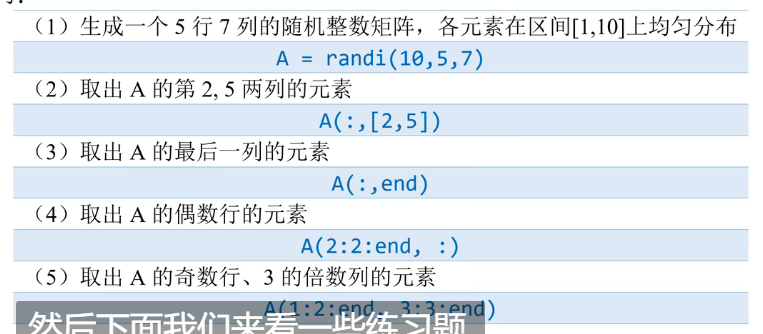

1. 

B = randi([1,10] ,5 , 7)

B =      5     7     8     2     8     3     3
     4     7     1    10     9     9     4
     9     4    10     3     5     7     8
    10     8     7     3     5    10     4
     8     2     9     5     8     2     7


2. 

B(:,[2 5])

ans =      7     8
     7     9
     4     5
     8     5
     2     8


3. 

B(:,end)

ans =      3
     4
     8
     4
     7


4. 

B(2:2:end , :)

ans =      4     7     1    10     9     9     4
    10     8     7     3     5    10     4


5. 

B(1:2:end , 3:3:end)

ans =      8     3
    10     7
     9     2


### 2-3 线性索引(单下标引用)

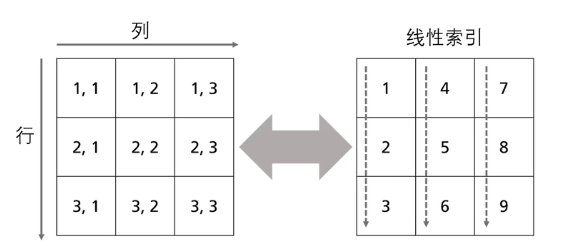

**A(:)命令:将A中所有元素按照线性索引的顺序重构成一个列向量**

A(:)

ans =     10
     5
     8
     8
     3
     3
    10
    10
     5
     4


**下标转换函数(用的少)**

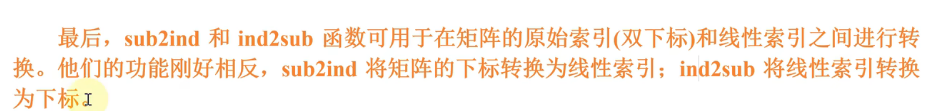

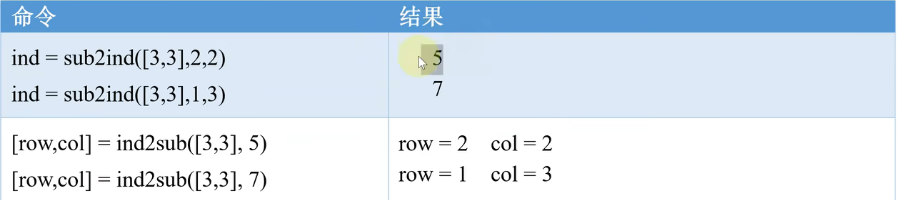

## 3. 矩阵元素的修改和删除

- 其实很简单,矩阵就是向量集合呗,所以很相似

- 就一句话 : **矩阵1( 向量1 , 向量2 ) = 矩阵2**

- 矩阵1为待修改删除引用的矩阵 , 向量1为选择的行数 , 向量2为选择的列数 , 矩阵2为想要修改成的数据集 , 千万记得需要与向量1,2的行列对应

% 样本矩阵
A = [1:4 ; 2:5 ; 3 : 6]

A =      1     2     3     4
     2     3     4     5
     3     4     5     6


% 1. 单个引用/修改
A(1,3) = 100 ;
A(1,3)

ans = 100

% 2. 多个引用/修改
A(1:2 , [2 3] ) = [200 , 200 ; 200 200] % 1:2表示[1 , 2] , 也就是第1行和第2行

A =      1   200   200     4
     2   200   200     5
     3     4     5     6


% 3. 线性索引引用/修改
A(4) = 300

A =      1   300   200     4
     2   200   200     5
     3     4     5     6


% 4. 越界情况
A(4,5) = 400

A =      1   300   200     4     0
     2   200   200     5     0
     3     4     5     6     0
     0     0     0     0   400


% 5. 删除:通常只能整行/列删除矩阵
A(: , 1) = []

A =    300   200     4     0
   200   200     5     0
     4     5     6     0
     0     0     0   400


## 4. 矩阵的拼接和重复

- 易错:要知道拼接是整体拼接 , 重复分为两种,一种是矩阵重复,其实也是拼接 , 只是规模化了 , 第2种是是元素重复,就是相邻元素重复!

### 4-1 矩阵拼接

- 横向拼接

- [A B] or horzcat(A,B) or  cat(2,A,B)

- 纵向拼接

- [A ; B] or vertcat(A,B) or cat(1,A,B)

A = [2:3 ; 5:6]

A =      2     3
     5     6


B = [1 3 ; 2 4]

B =      1     3
     2     4


% 横向拼接
horzcat(A , B)

ans =      2     3     1     3
     5     6     2     4


[A , B]

ans =      2     3     1     3
     5     6     2     4


% 纵向拼接
vertcat(A , B)

ans =      2     3
     5     6
     1     3
     2     4


[A ; B]

ans =      2     3
     5     6
     1     3
     2     4


% 拼接更多
[A B A]

ans =      2     3     1     3     2     3
     5     6     2     4     5     6


horzcat(A , B , A)

ans =      2     3     1     3     2     3
     5     6     2     4     5     6


### 4-2 矩阵的重复

- 矩阵重复

- repmat(A,m,n)        repeat matrix , 行方向上重复m次,列方向上重复n次

- 元素重复

- repelem(A , n) /   repelem(A.m.n) :    repeat 重复+element 元素）

repmat(A , 3 , 2)   % 重复一次相当于不变

ans =      2     3     2     3
     5     6     5     6
     2     3     2     3
     5     6     5     6
     2     3     2     3
     5     6     5     6


% 1. 重复向量的元素
B = [1 2 3] ;
repelem(B , 2)

ans =      1     1     2     2     3     3


repelem(B , [1 5 6])    % 第1个元素重复1次 , 第2个重复5次 , 第3个重复6次

ans =      1     2     2     2     2     2     3     3     3     3     3     3


% 2. 针对矩阵进行重复
% repelem(A , 向量1 , 向量2)    沿着行方向,第一行重复向量1(1)遍,...,沿着列方向,第一列重复向量2(1)遍
C = [1 2 3 ; 4:6 ; 7:9]

C =      1     2     3
     4     5     6
     7     8     9


repelem(C , [1 2 1] , [2 3 4])

ans =      1     1     2     2     2     3     3     3     3
     4     4     5     5     5     6     6     6     6
     4     4     5     5     5     6     6     6     6
     7     7     8     8     8     9     9     9     9


## 5. 矩阵的一些函数和操作

### 5-1 矩阵的重构和重新排列

### 5-2 reshape函数：更改矩阵的形状

### 5-3 sort函数：对向量或者矩阵进行排序

### 5-4 sortrows函数：基于某一列对矩阵

### 5-5 flip fliplr flipud函数

### 5-6 rot90函数：对矩阵进行旋转